### Choose chromosome

% note this only works for chromosomes 1 and 2
chromosome_of_interest = 'chr1';

### Choose transcription factor

can search for common TFs in [find_popular_TF.mlx](find_popular_TF.mlx_)

TF_of_interest = 'CTCF';

## Read sequence

% tic
% 
% % filename = strcat("Human Genome/", chromosome_of_interest, "_shorter.txt")
% 
% f = fopen(filename,'rt');
% chrm_sequence = fgetl(f);
% toc
% L = length(chrm_sequence)
% fclose(f);
filename = 'Human Genome/chr1.fa';
reads = fastaread(filename);
chrm_sequence = reads.Sequence;

chrm_sequence = upper(string(chrm_sequence));

### Get the PWM for chosen TF

[pwm_matrix, TF_binding_length] = getPWM(TF_of_interest);
TF_binding_length

TF_binding_length = 15

% save('CTCF_PWM', "pwm_matrix")

## Get TF Binding Positions if not already saved

load_name = strcat(TF_of_interest, '_', chromosome_of_interest,  '_binding_positions')

load_name = 'CTCF_chr1_binding_positions'

load(load_name, "TF_binding_pos")

stop_searching = 10000

### Create New Positions If not Saved

% TF_binding_pos = get_TF_binding_pos(chromosome_of_interest,TF_of_interest, stop_searching)

TF_binding_pos =            4      762711           0
           4      762889           0
           6      840115           0
           6      840798           1
          13      894643           0
          13      894675           0
          15      902593           1
          16      911601           1
          19      934728           1
          21      949890           1


### Overwrite positions

% save_name = strcat(TF_of_interest, '_', chromosome_of_interest,  '_binding_positions')

save_name = 'CTCF_chr1_binding_positions'

% save(save_name, "TF_binding_pos")

## Get Actual Positions

actual_positions = [];

## Calculate My Own TWM to confirm accuracy of positions

nukes = {'A', 'C', 'G', 'T'};
my_own_TWM_row = repmat([0], 1, TF_binding_length);
my_own_TWM = repmat(my_own_TWM_row, 4, 1)

my_own_TWM =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Calculate Minimum Score of a binding region for a particular TF.

scores = [];

for i=1:length(TF_binding_pos)
% for i=1:10
    site_id_num = TF_binding_pos(i, 1);
    start = TF_binding_pos(i, 2);
    strand = TF_binding_pos(i, 3);
    
    if strand == 1
        for k = 1:TF_binding_length
            r = extractBetween(chrm_sequence,start+k,start+k);
            pos = find(nukes == r);
            my_own_TWM(pos, k) = my_own_TWM(pos, k) + 1;
        end
        r = extractBetween(chrm_sequence,start+1,start+TF_binding_length);
        score =  get_score(0, r, pwm_matrix, TF_binding_length, 1);
        scores = [scores; score];
        pos1 = [site_id_num, start+1, 1, ceil(score)];
        actual_positions = [actual_positions; pos1];
    else 
        for k = 1:TF_binding_length
            r = extractBetween(chrm_sequence,start+k,start+k);
            pos = find(nukes == r);
            my_own_TWM(5-pos, TF_binding_length-k+1) = my_own_TWM(5-pos, TF_binding_length-k+1) + 1;
        end
        r = extractBetween(chrm_sequence,start+1,start+TF_binding_length);
        score = get_score(0, r, pwm_matrix, TF_binding_length, 0);
        scores = [scores; score];
        pos1 = [site_id_num, start+1, 0, ceil(score)];
        actual_positions = [actual_positions; pos1];
    end

end
min(scores)

ans = -16.2258

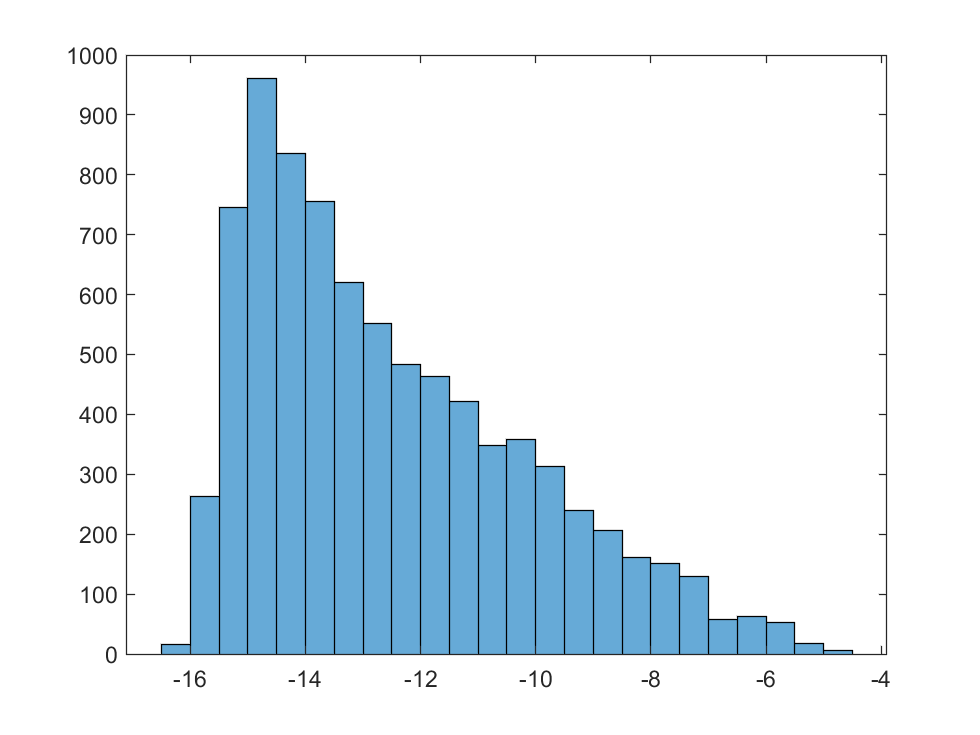

h =   Histogram with properties:

             Data: [8219×1 double]
           Values: [16 263 745 961 836 755 620 552 484 464 422 348 358 313 239 207 161 151 129 58 62 52 17 6]
          NumBins: 24
         BinEdges: [-16.5000 -16 -15.5000 -15 -14.5000 -14 -13.5000 -13 -12.5000 -12 -11.5000 -11 -10.5000 -10 -9.5000 -9 -8.5000 -8 -7.5000 -7 -6.5000 -6 -5.5000 -5 -4.5000]
         BinWidth: 0.5000
        BinLimits: [-16.5000 -4.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h = histogram(scores)

my_own_TWM = my_own_TWM / length(actual_positions)

my_own_TWM =     0.0658    0.0489    0.0916    0.0566    0.0004    0.2817    0.0068         0    0.0913    0.2397    0.0251    0.1516    0.0156    0.0475    0.1326
    0.4157    0.5497    0.0788    0.7682    0.9854    0.5875    0.6399    0.9955    0.1347    0.1472    0.4395    0.1980    0.0091    0.1431    0.5235
    0.4471    0.0552    0.6691    0.1044    0.0001    0.0607    0.0080    0.0045    0.0296    0.5007    0.5070    0.0898    0.9500    0.7281    0.1365
    0.0713    0.3461    0.1605    0.0708    0.0141    0.0701    0.3453         0    0.7445    0.1124    0.0285    0.5607    0.0253    0.0814    0.2073


exp(pwm_matrix) - 0.001

ans =     0.0540    0.0240    0.0680    0.0420    0.0000    0.2620    0.0040    0.0000    0.0320    0.2660    0.0200    0.0800    0.0100    0.0260    0.1260
    0.3180    0.6460    0.0420    0.7900    0.9940    0.6660    0.6180    0.9980    0.0640    0.0900    0.3440    0.1940    0.0020    0.0660    0.5940
    0.5660    0.0240    0.7920    0.0620    0.0000    0.0460    0.0020    0.0020    0.0080    0.5640    0.6200    0.0440    0.9760    0.8400    0.0740
    0.0620    0.3060    0.0980    0.1060    0.0060    0.0260    0.3760    0.0000    0.8960    0.0800    0.0160    0.6820    0.0120    0.0680    0.2060


dif = my_own_TWM - (exp(pwm_matrix) - 0.001);
mean(mean(dif))

ans = -5.5403e-18

actual_positions

actual_positions =            1      237750           1         -13
           1      237752           0         -10
           1      237762           0         -12
           2      521533           1         -11
           2      521535           0          -9
           2      521545           0         -12
           3      714183           1         -13
           3      714273           0         -11
           5      805272           1         -13
           5      805298           1         -12


## Predict Positions for PWM

% if you have a global minscore
% load(strcat(TF_of_interest, "_minscore"))
% threshold = minscore
% otherwise use local score
threshold = -20

threshold = -20

[positions, pred_sequences] = predict_positions(chrm_sequence, chromosome_of_interest, pwm_matrix, TF_binding_length, threshold);

i = 7405

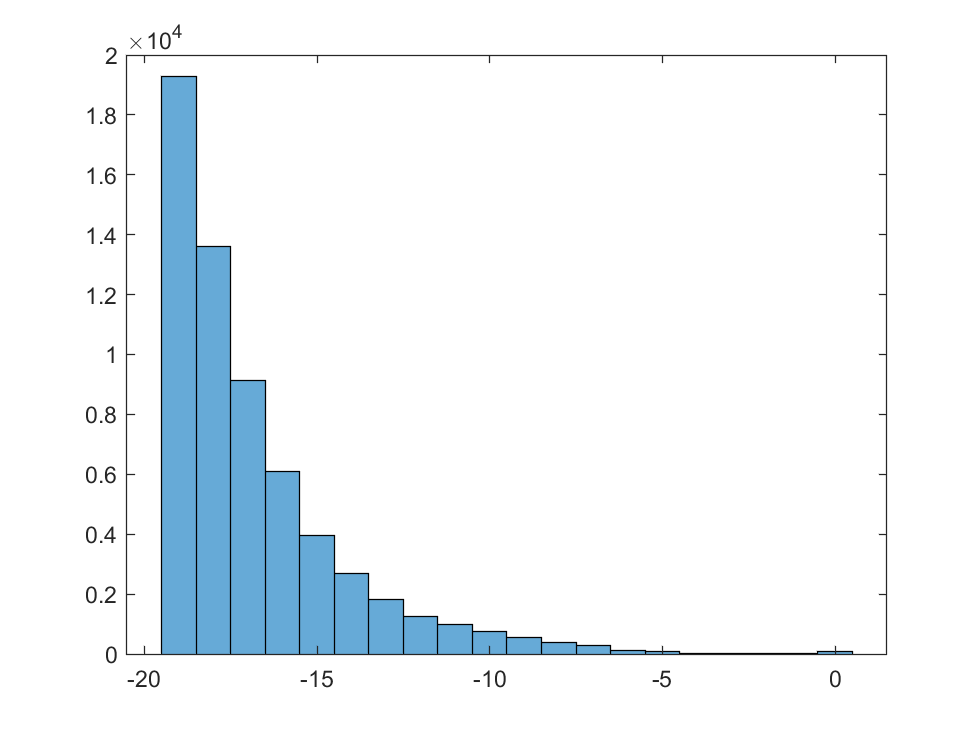

histogram(positions(:, 4))

## Compare scores of found vs not found

[found,found_scores, not_found_scores] = check_found(chrm_sequence, positions,actual_positions, pwm_matrix, TF_binding_length);

mean(found_scores)

ans = -12.4971

std(found_scores)

ans = 2.3858

mean(not_found_scores)

ans = -14.2758

found

found = 8218

percentageFound = found / length(actual_positions)

percentageFound = 0.9999

found / length(positions(:, 1))

ans = 0.1328

## Positive vs negative

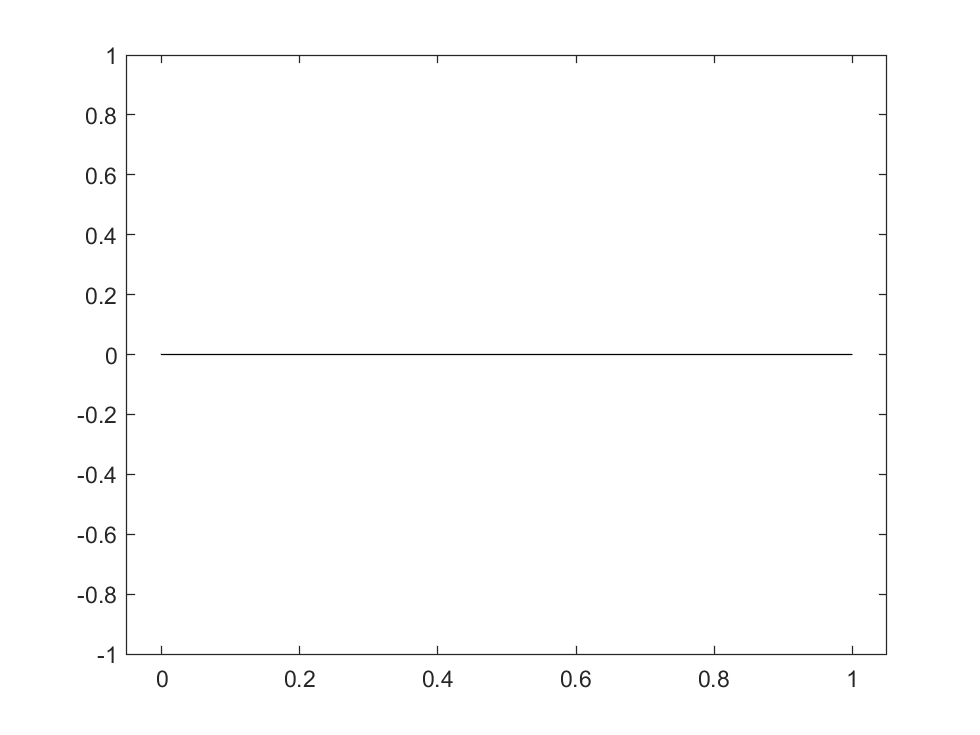

positive = 0;
success = false;
positive_scores = [];
negative_scores = [];
false_sequences = [];

merged_data = [];

for k=1:length(positions)
    for i=1:length(actual_positions)
        if positions(k,2) == actual_positions(i, 2) && positions(k, 3) == actual_positions(i, 3)
%             positive = positive + 1;
%             region = extractBetween(chrm_sequence,actual_positions(i, 2),actual_positions(i, 2) + TF_binding_length + 1);
%             score = get_score(0, region, pwm_matrix, TF_binding_length, actual_positions(i, 3));
%             merged_data = [merged_data; actual_positions(i, :) 1];
%             positive_scores = [positive_scores; ceil(score)];
            success= true;
            break; 
        end
    end
    if success == false
%         false;
%         region = extractBetween(chrm_sequence,positions(k, 2),positions(k, 2) + TF_binding_length + 1);
%         score = get_score(0, region, pwm_matrix, TF_binding_length, positions(k, 3));
%         negative_scores = [negative_scores; ceil(score)];
%         merged_data = [merged_data; positions(k, :) 0];
        false_sequences = [false_sequences; pred_sequences(k, 1)];
    end
    success = false;
end

histogram(positive_scores)

histogram(negative_scores)

positive

positive = 0

percentagePositive = positive / length(positions)

percentagePositive = 0

positive / length(actual_positions(:, 1))

ans = 0

merged_data


merged_data =

     []



false_sequences = cellstr(false_sequences)

false_sequences = 52812×1 cell array
    {'GATCCTTGAAGCACCCCCAAGGGCATCTTCTCAAA'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN'}
    {'NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN

save("false_sequences_longer", "false_sequences")

## Save Data

save_name = strcat(TF_of_interest, '_',  chromosome_of_interest, '_positions3')
save(save_name, "merged_data")